# QAM MODULATION

%%symbolic
    syms t
    
    %signal frequency
    F1=1;
    
    %signal being sampled
        x=cos(2*pi*t*F1)

$$x = \cos\left(2\,\pi \,t\right)$$

        y=3*cos(2*pi*F1*t)

$$num\_V = 3\,\cos\left(2\,\pi \,t\right)$$

    
    %%cariier freq
        Fc=10

Fc = 10

    %%after modulation
        v=x*cos(2*pi*Fc*t)+y*sin(2*pi*Fc*t)

$$v = \cos\left(2\,\pi \,t\right)\,\cos\left(20\,\pi \,t\right)+3\,\cos\left(2\,\pi \,t\right)\,\sin\left(20\,\pi \,t\right)$$

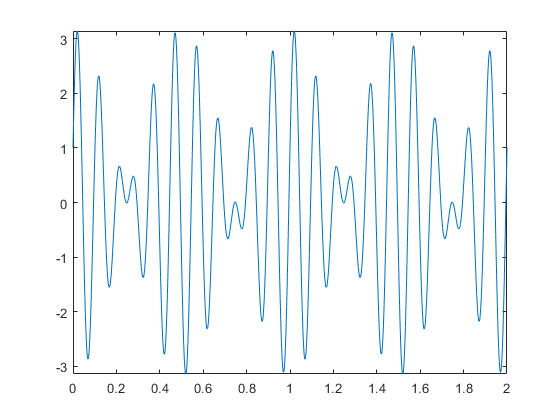

    fplot(v,[0,2/F1])

        
    max_w=6*pi*max(F1,Fc);
    W_range=linspace(0,25*pi,1000)

W_range =          0    0.0786    0.1572    0.2359    0.3145    0.3931    0.4717    0.5503    0.6289    0.7076    0.7862    0.8648    0.9434    1.0220    1.1007    1.1793    1.2579    1.3365    1.4151    1.4938    1.5724    1.6510    1.7296    1.8082    1.8868    1.9655    2.0441    2.1227    2.2013    2.2799    2.3586    2.4372    2.5158    2.5944    2.6730    2.7516    2.8303    2.9089    2.9875    3.0661    3.1447    3.2234    3.3020    3.3806    3.4592    3.5378    3.6164    3.6951    3.7737    3.8523


    ffv=fourier(v)

$$ffv = \frac{\pi \,\left(\delta (w-18\,\pi )+\delta (w+18\,\pi )\right)}{2}+\frac{\pi \,\left(\delta (w-22\,\pi )+\delta (w+22\,\pi )\right)}{2}-\frac{3\,\pi \,\left(\delta (w-18\,\pi )-\delta (w+18\,\pi )\right)\,\mathrm{i}}{2}-\frac{3\,\pi \,\left(\delta (w-22\,\pi )-\delta (w+22\,\pi )\right)\,\mathrm{i}}{2}$$

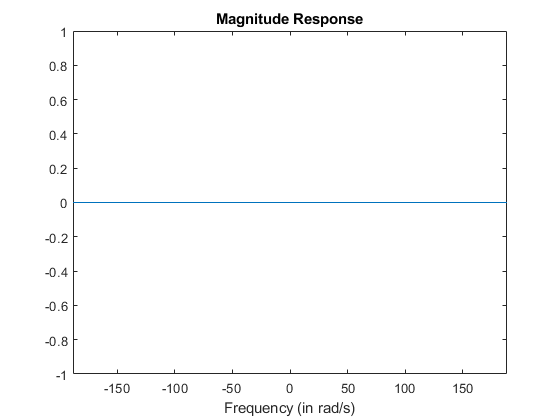

    fplot(ffv,[-max_w,max_w]);
       xlabel('Frequency (in rad/s)');
       title('Magnitude Response');

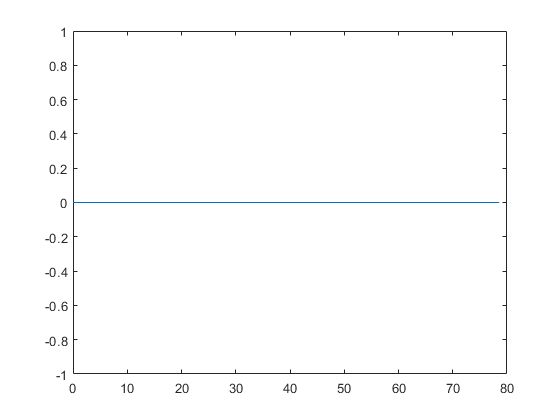

    F_resp=abs(subs(ffv,W_range));
    plot(W_range,F_resp)

%%numeric

%%initialisation
    f=2; %frequency of the impulse in Hz
    fs=max_w*10/pi; % sample frequency is 10 times higher
    time=-12:1/fs:12; % time vector
    num_V=double(subs(v,t,time))

num_V =     1.0000    1.3080    1.6015    1.8772    2.1319    2.3628    2.5673    2.7432    2.8884    3.0015    3.0811    3.1265    3.1373    3.1133    3.0550    2.9631    2.8387    2.6834    2.4991    2.2879    2.0522    1.7950    1.5191    1.2278    0.9244    0.6124    0.2954   -0.0231   -0.3393   -0.6498   -0.9511   -1.2398   -1.5128   -1.7671   -1.9999   -2.2089   -2.3917   -2.5466   -2.6721   -2.7669   -2.8302   -2.8617   -2.8612   -2.8291   -2.7660   -2.6730   -2.5514   -2.4029   -2.2295   -2.0333


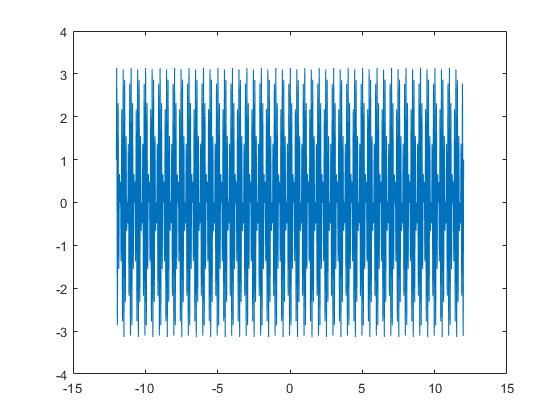

    plot(time,num_V);

        
    N=size(time,2)

N = 14401

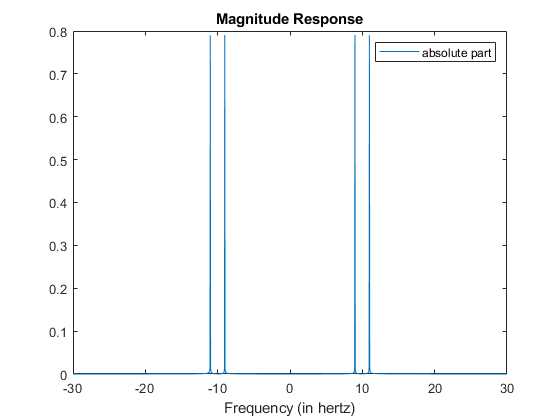

    Y = fftshift(fft(num_V));
   %%Frequency specifications:
   dF = fs/N;                      % hertz
   f = -fs/2:dF:fs/2-dF;           % hertz
   %%Plot the spectrum:
   figure;

   plot(f,abs(Y)/N,'DisplayName','absolute part')
   legend
   
   xlabel('Frequency (in hertz)');
   title('Magnitude Response');
    xlim([-fs/20 fs/20])
   hold off